mmSetFigPublication

Default figure color set to white.
Default font size set to 16.0.

## Chair Analysis

Load table

doc = matlab.desktop.editor.getActive;    % active editor document
T = readtable(fullfile(fileparts(doc.Filename), "CapstoneDatabase.xlsx"))

T = 196×10 table
    year     Lstudent_name        Fstudent_name                                                                               project_name                                                                                    chair                 mentor                    x3rdmember              cap_category       deliverable_type        deliverable_SUBtype  
    ____    _______________    ___________________    _____________________________________________________________________________________________________________________________________________________________    ___________________    ___________________    _____________________________    _____________    

ans = 16×1 cell array
    {0×0 char              }
    {'Caley Orr'           }
    {'Calude Seltrennikoff'}
    {'Chelsea Lohman'      }
    {'Danielle Royer'      }
    {'Ernesto Salcedo'     }
    {'John Caldwell'       }
    {'John Thompson'       }
    {'LIsa Lee'            }
    {'Lisa Lee'            }
    {'Maureen Stabio'      }
    {'Mike Pascoe'         }
    {'Norma Wagoner'       }
    {'Paul Morse'          }
    {'Thomas Finger'       }
    {'Vic Spitzer'         }


## Read table

doc = matlab.desktop.editor.getActive;    % active editor document
T = readtable(fullfile(fileparts(doc.Filename), "CapstoneDatabase.xlsx"))

T = readtable("ListCapstoneProjects.csv")

T = 106×4 table
    Year             Student                      CapstoneMentor                                                                                          CapstonePresentationTitle                                                                            
    ____    _________________________    _________________________________    _________________________________________________________________________________________________________________________________________________________________________________

    2024    {'Kerry Barba'          }    {'Chelsea Lohman, PhD'          }    {'Compassion in the Cadaver Lab: When Donor Gender Identity and Virtual Learning Intersect'                                                                                     }
    2024    {'Ruby Martini'         }    {'John Thompson, PhD'           }    {

T.mentor = categorical(T.mentor);

Error using  .  (line 236)
Unrecognized table variable name 'mentor'.

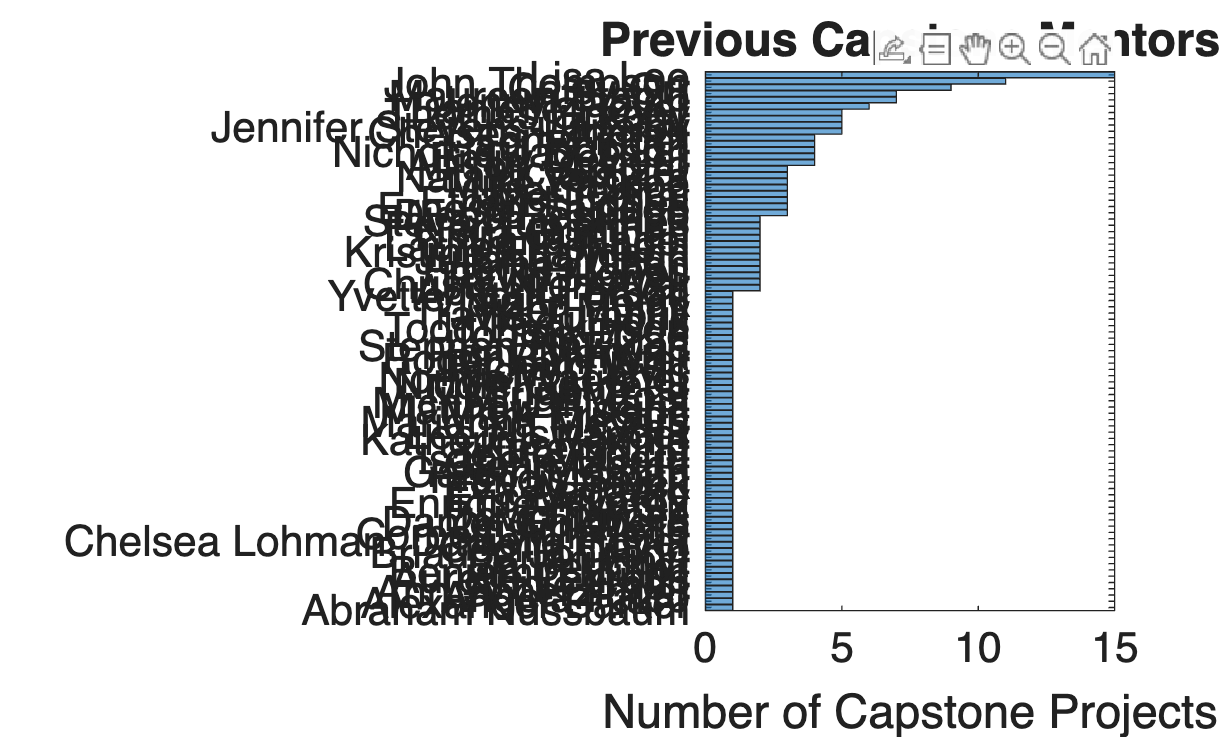

clf;
histogram(T.mentor,Orientation='horizontal',DisplayOrder='ascend')
title("Previous Capstone Mentors")
xlabel('Number of Capstone Projects')

textData = string(T.project_name);
cleanedData = tokenizedDocument(textData);
cleanedData = addPartOfSpeechDetails(cleanedData);
cleanedData = removeStopWords(cleanedData);
cleanedData = normalizeWords(cleanedData,"Style",'lemma');
cleanedData = erasePunctuation(cleanedData);
cleanedData = removeShortWords(cleanedData,2);
cleanedBag = bagOfWords(cleanedData);
cleanedBag = removeInfrequentWords(cleanedBag,2);
cleanedBag=removeEmptyDocuments(cleanedBag)

cleanedBag =   bagOfWords with properties:

        NumWords: 141
          Counts: [176×141 double]
      Vocabulary: ["virtual"    "histology"    "laboratory"    "interactive"    "education"    "segmentation"    "taste"    "cell"    "mouse"    "nerve"    "modeling"    "scan"    "module"    "impact"    "anatomy"    "pathology"    …    ] (1×141 string)
    NumDocuments: 176


figure(Visible="on");
wordcloud(cleanedBag)

## Department data

mF = "/Users/ernesto/github/MHACapstone/resources/CapstoneCommitteeMentors.csv";
mT = readtable(mF); % load Mentor Table (from Jennifer's data)
mT.Department = categorical(mT.Department);

unique(mT.FacultyIDFK)

ans = 105×1 cell array
    {'Aagaard, Eva'              }
    {'Alvarez, Enrique'          }
    {'Apgar, Georgann'           }
    {'Bannister, Roger'          }
    {'Barker, Alexander'         }
    {'Bettcher, Brianne'         }
    {'Blezinski Johnson, Briauna'}
    {'Buard, Isabelle'           }
    {'Caino, Cecilia'            }
    {'Cale, Andrew'              }
    {'Carry, Mike'               }
    {'Chen, Chang Hui (Annie)'   }
    {'Chen, James'               }
    {'Christiansen, Cory'        }
    {'Corral, Janet'             }
    {'Davis, Rachel'             }
    {'DeBoer, Emily'             }
    {'Deutchman, Mark'           }
    {'Di Maria, Michael'         }
    {'Eckle, Tobias'             }
    {'Eissa, Hesham'             }
    {'Erickson, Mark'            }
    {'Erlandson, Kristine'       }
    {'Falco, Angela'             }
    {'Finger, Thomas'            }
    {'Fishbein, Lauren'          }
    {'Frank, Guido'              }
    {'Fridman, Vera'            

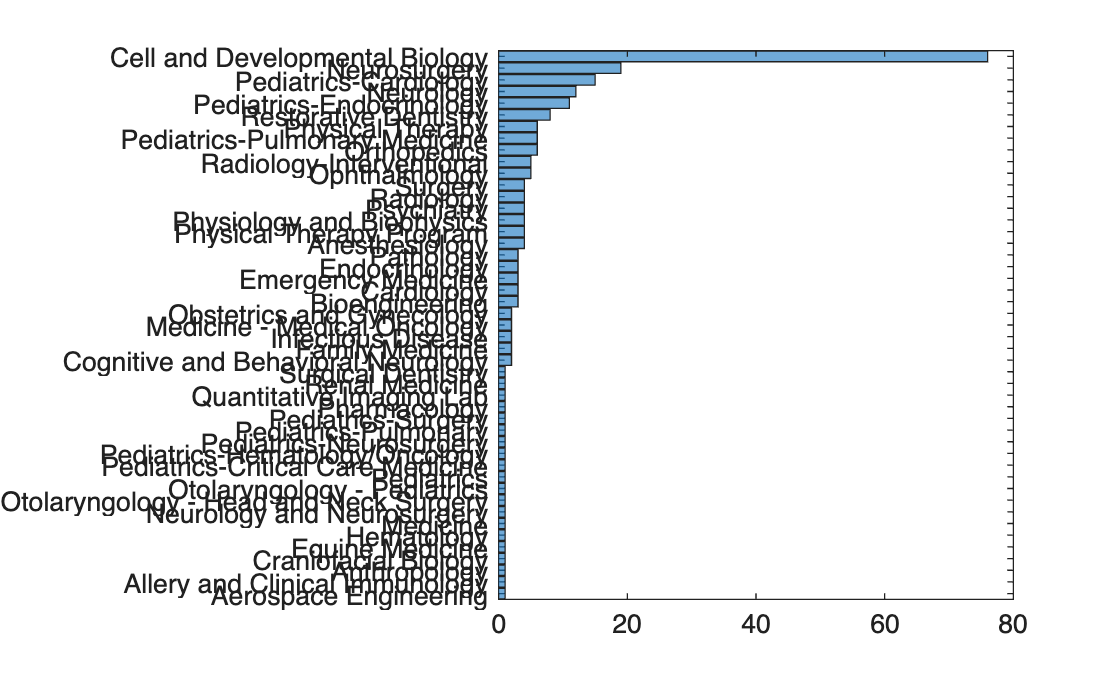

figure;
histogram(deptO,Orientation="horizontal")

### Merge Pediatrics

cats = categories(deptO);
laCats = startsWith(cats,'Pediatrics-');
pedCats = cats(laCats);
deptO = mergecats(deptO,pedCats,'Pediatrics');
summary(deptO)


deptO: 248×1 categorical

     Aerospace Engineering                        1 
     Allery and Clinical Immunology               1 
     Anthropology                                 1 
     Craniofacial Biology                         1 
     Equine Medicine                              1 
     Hematology                                   1 
     Medicine                                     1 
     Neurology and Neurosurgery                   1 
     Otolaryngology - Head and Neck Surgery       1 
     Otolaryngology - Pediatrics                  1 
     Pediatrics                                  38 
     Pharmacology                                 1 
     Quantitative Imaging Lab                     1 
     Renal Medicine          

### Sort by Instance

[~,idx] = sortrows(countcats(deptO),"descend"); 
deptO = reordercats(deptO,idx); % make ordinal by Dept Instance
summary(deptO)


deptO: 248×1 categorical

     Cell and Developmental Biology              76 
     Pediatrics                                  38 
     Neurosurgery                                19 
     Neurology                                   12 
     Restorative Dentistry                        8 
     Orthopedics                                  6 
     Physical Therapy                             6 
     Ophthalmology                                5 
     Radiology-Interventional                     5 
     Anesthesiology                               4 
     Physical Therapy Program                     4 
     Physiology and Biophysics                    4 
     Psychiatry                                   4 
     Radiology               

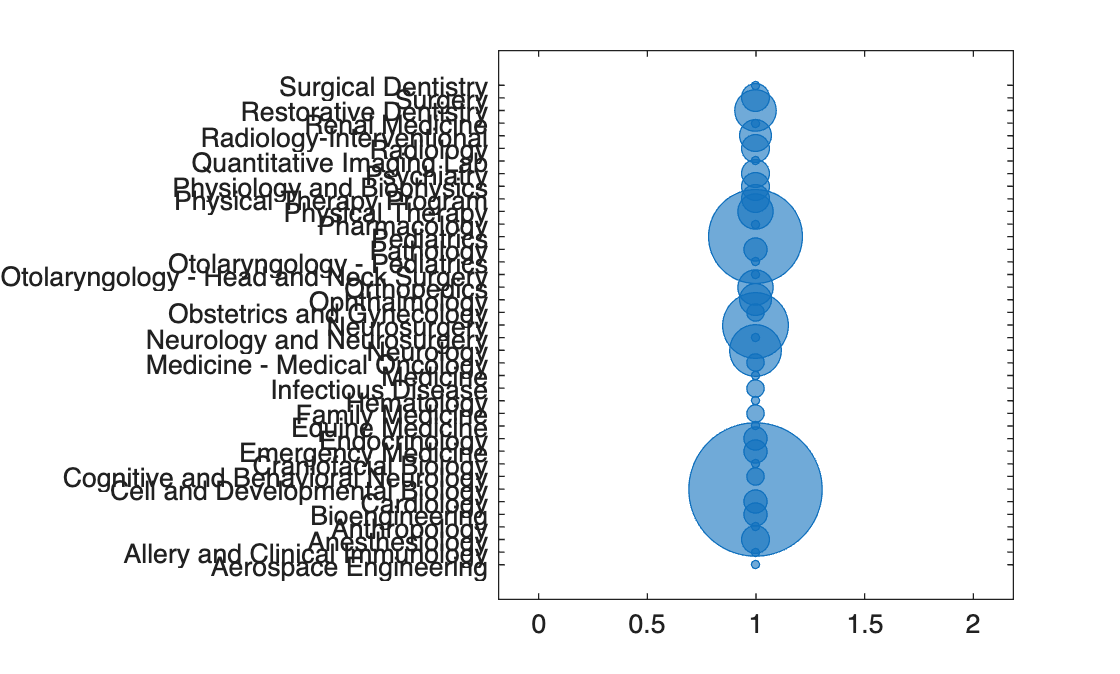

figure;
bubblechart(ones(39,1),categorical(categories(deptO)),countcats(deptO))

t = table(categorical(categories(deptO)), countcats(deptO),VariableNames=["Dept" "Count"]);
t.XOrder = [ones(10,1); ones(10,1)*2; ones(10,1)*3; ones(9,1)*4]; 
 t.YOrder = [(1:10)' ; (1:10)'; (1:10)';(1:9)']

t = 39×4 table
                 Dept                 Count    XOrder    YOrder
    ______________________________    _____    ______    ______

    Cell and Developmental Biology     76        1          1  
    Pediatrics                         38        1          2  
    Neurosurgery                       19        1          3  
    Neurology                          12        1          4  
    Restorative Dentistry               8        1          5  
    Orthopedics                         6        1          6  
    Physical Therapy                    6        1          7  
    Ophthalmology                       5        1          8  
    Radiology-Interventional            5        1          9  
    Anesthesiology                      4        1         10  
    Physical Therapy Program            4        2          1  
    Physiology a

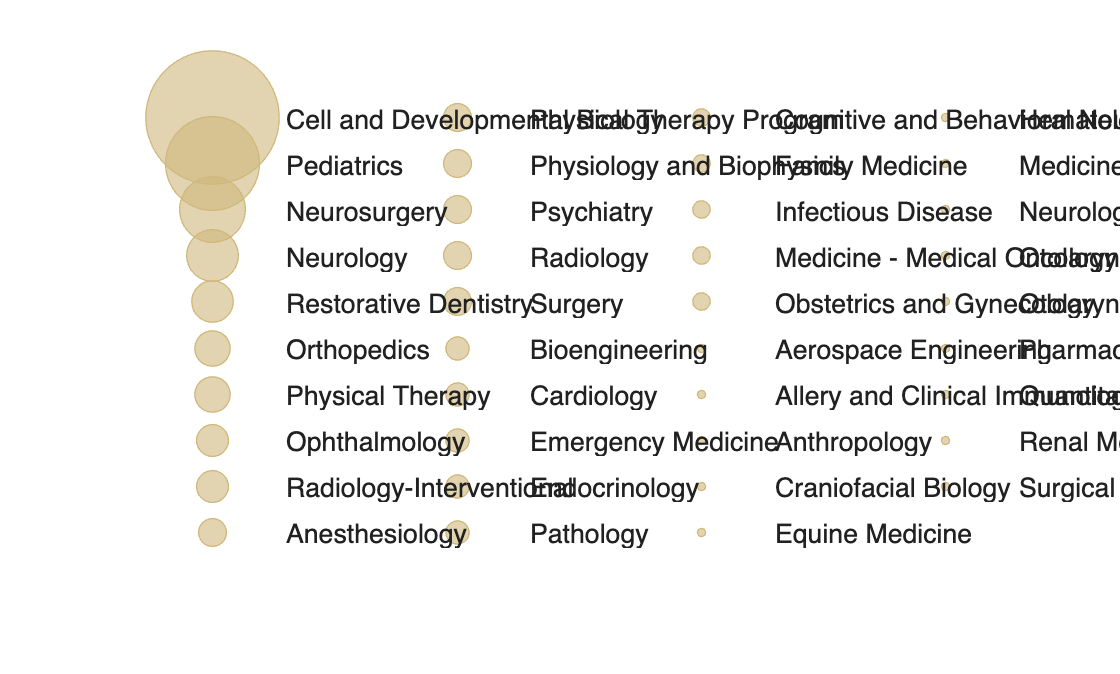

figure;
bubblechart(t.XOrder,t.YOrder, t.Count,"#CFB87C")
axis ij off
str = string(t.Dept);
str(end+1) = "";
str = reshape(str,10,4);
for n=1:height(t)
    text(t.XOrder(n)+.3,t.YOrder(n),str(n))
end

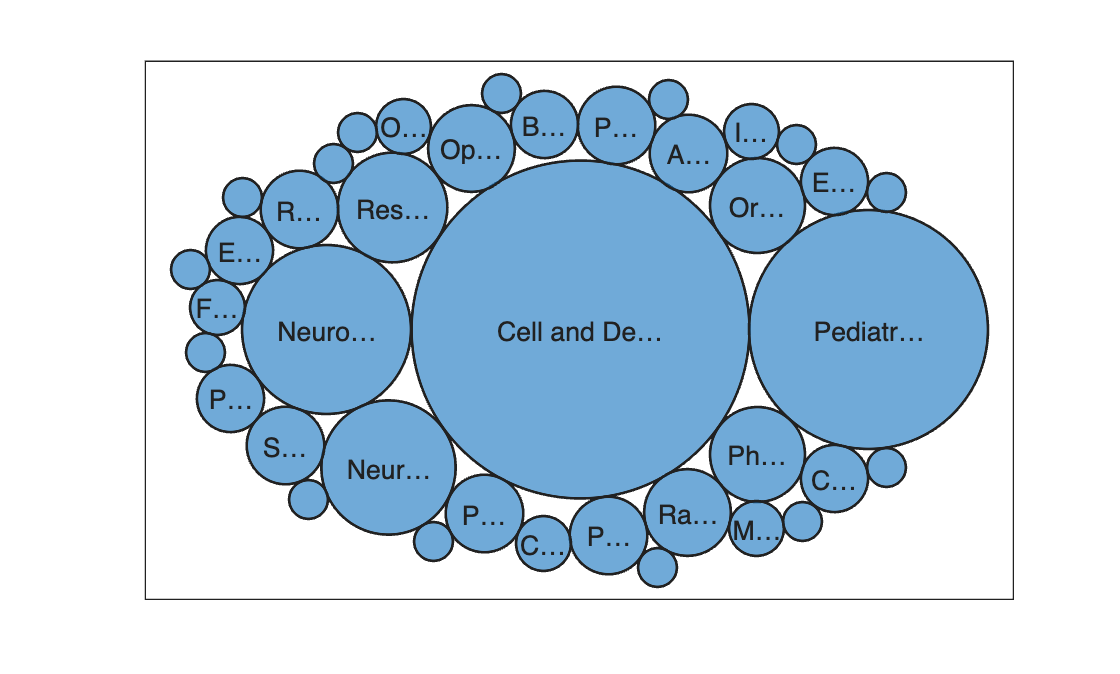

figure;
bubblecloud(t,"Count","Dept")



deptO = categorical(mT.Department)
countcats(mT.Department);

ans =      1
     1
     4
     1
     3
     3
    76
     2
     1
     3
     3
     1
     2
     1
     2


categories(mT.Department)

ans = 47×1 cell array
    {'Aerospace Engineering'                 }
    {'Allery and Clinical Immunology'        }
    {'Anesthesiology'                        }
    {'Anthropology'                          }
    {'Bioengineering'                        }
    {'Cardiology'                            }
    {'Cell and Developmental Biology'        }
    {'Cognitive and Behavioral Neurology'    }
    {'Craniofacial Biology'                  }
    {'Emergency Medicine'                    }
    {'Endocrinology'                         }
    {'Equine Medicine'                       }
    {'Family Medicine'                       }
    {'Hematology'                            }
    {'Infectious Disease'                    }
    {'Medicine'                              }
    {'Medicine - Medical Oncology'           }
    {'Neurology'                             }
    {'Neurology and Neurosurgery'            }
    {'Neurosurgery'                          }
    {'Obstetrics and Gynecology'      

[~,idx] = sortrows(countcats(mT.Department))

idx =      1
     2
     4
     9
    12
    14
    16
    19
    24
    25
    27
    29
    31
    32
    33
